# Across-trial phase-lag index: tutorial

The following is a step-by-step tutorial demonstrating how the function **across_trial_pli.m** is implemented. 

## Generate pseudo EEG data.

First, let's generate event-related EEG data with the following parameters:

- 70 trials

- 64 channels

- 6000 samples per trial

- Sampling rate of 1000Hz

Let's make it so that each channel time-series is a weighted combination of pink noise (i.e., 1/*f*) and two sinusoids (10 Hz and 25 Hz), where the phase of each is drawn uniformly at random from -pi to pi.

% Define the dimensions of the data.
n_channels = 64;
n_samples = 6000;
n_trials = 70;
samp_rate = 1000;

% Define the frequencies and weights of the sine waves.
peaks = [];
peaks.hz = [10,25];
peaks.w = [.1,.05];

% Define the amount of noise.
noise = 3;

% Set seed for reproducibility
rng(1)

xs = [];
xs.raw = zeros(n_channels,n_samples,n_trials);
time = 0:(1/samp_rate):(n_samples/samp_rate)-(1/samp_rate);

for trial = 1:n_trials
    for channel = 1:n_channels    
        sine_1 = sin(2*pi*peaks.hz(1)*time + rand(1)*pi);
        sine_2 = sin(2*pi*peaks.hz(2)*time + rand(1)*pi);         
        xs.raw(channel,:,trial) = peaks.w(1)*sine_1 + peaks.w(2)*sine_2;
    end
    xs.raw(:,:,trial) = xs.raw(:,:,trial) + noise*pinknoise(n_samples,n_channels)';
end

Let's take a look at the time-series of a single channel to ensure everything worked.

% Plot a single channel time-series.

figure('Position',[505 428 895 369]);
plot(xs.raw(1,:,1),'k');
xlim([650,1650])
ylim([-.5,.5])
xlabel('Time')
ylabel('Voltage ({\mu}V)')
title('Single channel time-series')

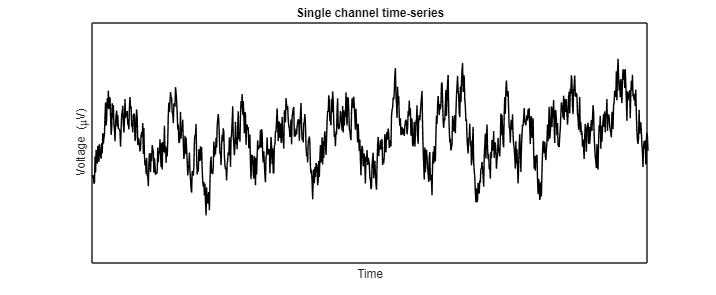

set(gca,'XTick',[], 'YTick', [])

Let's inspect the power spectral density of said time-series as well, to ensure that the oscillations we created are present as peaks. With real data, I suggest parameterizing this power spectrum to assess the characteristics of any peaks that exist within the data prior to implementing these analyses. See, for example: [https://fooof-tools.github.io/fooof/](https://fooof-tools.github.io/fooof/)

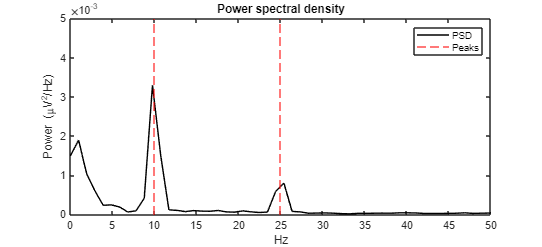

% Calcualte PSD.
[~,freq,~,psd] = spectrogram(xs.raw(1,:,1),samp_rate,[],[],samp_rate);
mean_psd = mean(psd,2);

% Plot.
figure('Position',[576 479 678 309]);
plot(freq,mean_psd,'k')
title('Power spectral density')
xlim([0,50])
ylim([0,.005])
xlabel('Hz')
ylabel('Power ({\mu}V{^2}/Hz)')
xline(peaks.hz,'--','color','red')
legend('PSD','Peaks')

## Create filter.

Now, let's create a band-pass filter so we can estimate the instantaneous phase of the oscillation at 10Hz. I'll use a window from 5-15Hz for this filter. However, visual inspection, as well as careful consideration of the research question (in terms of time/frequency resolution trade-off) is crucial in selecting this parameter. In an ideal world, the sensitivity of any results to a range of filter widths would be assessed.

% Specify range.
filt_band = [5 15];  

% Create filter.
filt_params = [];
filt_params.transition = mean(filt_band) * 0.2;                                                                   
filt_params.frequencies = [filt_band(1) - filt_params.transition, filt_band(1), filt_band(2), filt_band(2) + filt_params.transition];
filt_params.order = kaiserord(filt_params.frequencies, [0 1 0], [0.1 0.05 0.1], samp_rate);                                                                          
filt_params.coefficients = fir1(filt_params.order, filt_band*(2/samp_rate), 'bandpass');

The parameters of the filter are stored in the structure **filt_params**, shown here:

disp(filt_params)

      transition: 2
     frequencies: [3 5 15 17]
           order: 630
    coefficients: [-4.3094e-05 -4.3982e-05 -4.4236e-05 -4.3866e-05 -4.2887e-05 -4.1318e-05 -3.9179e-05 -3.6498e-05 -3.3305e-05 -2.9634e-05 … ]



## Apply filter, estimate instantaneous phase.

Now that we've created the filter, let's apply it and calculate the instantaenous phase of the resulting time-series using the Hilbert transform.

tic
for trial = 1:n_trials
   
    % Z-score.
    xs.norm(:,:,trial) = zscore(xs.raw(:,:,trial)')';
    
    % Filter.
    for channel = 1:n_channels
        xs.filtered(channel,:,trial)  = filtfilt(filt_params.coefficients, 1, squeeze(xs.norm(channel,:,trial)));
    end
    
    % Hilbert transform.
    xs.hilbert(:,:,trial) = hilbert(xs.filtered(:,:,trial));

    % Estiamte phase.
    xs.phase(:,:,trial) = angle(xs.hilbert(:,:,trial));

end
toc

Elapsed time is 29.805378 seconds.


The structure **xs** (time-series) includes all the intermediate processing steps: the raw signals, the z-scored signals, the band-pass filtered signals, the hilbert-transformed signals, and the instantaneous phase signals.

disp(xs)

         raw: [64×6000×70 double]
        norm: [64×6000×70 double]
    filtered: [64×6000×70 double]
     hilbert: [64×6000×70 double]
       phase: [64×6000×70 double]



Let's plot the raw signal against the band-pass filtered signal to ensure everything worked correctly.

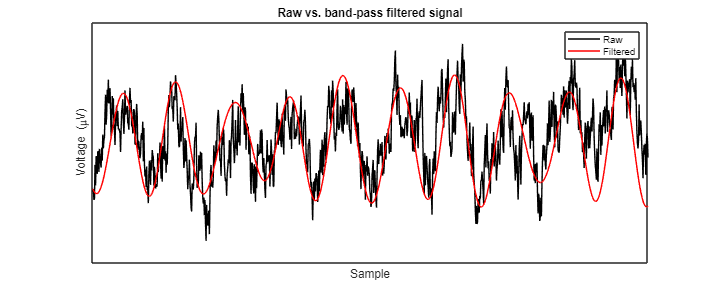

figure('Position',[505 428 895 369]);
plot(zscore(xs.raw(1,:,1)),'k')
hold on;plot(zscore(xs.filtered(1,:,1)),'color','red')
xlim([650,1650])
title('Raw vs. band-pass filtered signal')
legend('Raw','Filtered')
xlabel('Sample')
ylabel('Voltage ({\mu}V)')
set(gca,'XTick',[], 'YTick', [])

## Implement the across-trial phase-lag index.

Now let's go ahead and implement the analyses. First, let's define an in-line function that calculates the phase-lag index. See Stam et al. (2007) for details: [https://pubmed.ncbi.nlm.nih.gov/17266107/](https://pubmed.ncbi.nlm.nih.gov/17266107/)

pli_fx = @(phase_set_i,phase_set_j) abs(mean(sign(phase_set_i - phase_set_j),2));

Now let's test the function by calculating the across-trial PLI for channels *i* and *j*.

i = 8;
j = 32;

phase_set_i = squeeze(xs.phase(i,:,:));
phase_set_j = squeeze(xs.phase(j,:,:));

Let's visualize the angular distribution of the phase differences between channels *i* and* j *as a function of time.

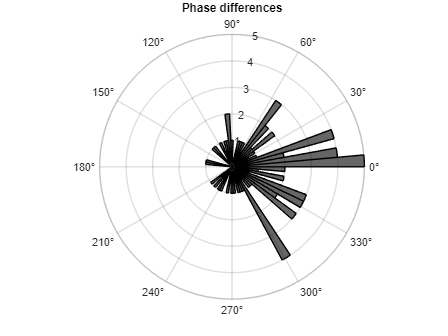

% Calculate phase differences.
phase_diffs = phase_set_i - phase_set_j;

% Plot
figure;
polarhistogram(phase_diffs(2851,:),n_trials,'facecolor','k')
title('Phase differences')

The PLI value for this set of phase differences is:

sample = 1000;
disp(pli_fx(phase_set_i(sample,:),phase_set_j(sample,:)))

    0.1143



Now, let's run that calculation for all possible channel pairs, and track the output in the variable **adjacency_tensor**.

tic

adjacency_tensor = zeros(n_channels,n_channels,n_samples);
channel_pairs = nchoosek(1:n_channels,2);

for ij = 1:length(channel_pairs)
    pair = channel_pairs(ij,:);
    pli = pli_fx(squeeze(xs.phase(pair(1),:,:)),squeeze(xs.phase(pair(2),:,:)));
    adjacency_tensor(pair(1),pair(2),:) = pli;
end
% Fill in symmetric values.
for sample = 1:n_samples
    adjacency_tensor(:,:,sample) = adjacency_tensor(:,:,sample)' + adjacency_tensor(:,:,sample);
end

toc

Elapsed time is 28.303595 seconds.


The variable **adjacency_tensor** is a 3 dimensional array with PLI adjacency matrices over time [Channel x Channel x Sample].

fprintf('\nDimensionality of adjacency tensor:')


Dimensionality of adjacency tensor:

disp(size(adjacency_tensor))

          64          64        6000



Let's plot the channel-by-channel adjacency matrix as a function of time (adjust the sample being shown using the slider).

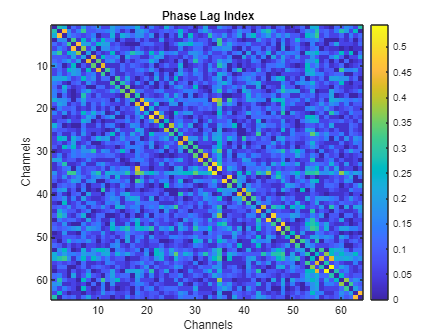

figure;
imagesc(adjacency_tensor(:,:,3923))
colorbar
xlabel('Channels')
ylabel('Channels')
title('Phase Lag Index')

Now let's see how to implement the same analyses using the function **across_trial_pli.m**

[adjacency_tensor, xs, filt_params] = across_trial_pli(xs.raw,samp_rate,filt_band);


Calculating across-trial phase-lag index...
Elapsed time is 58.207906 seconds.


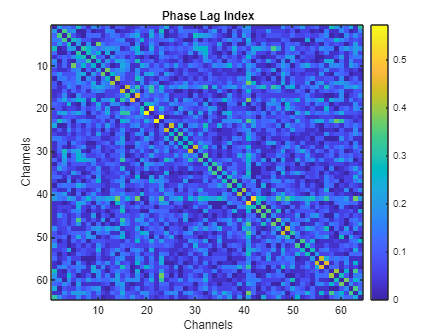

% Plot.
figure;
imagesc(adjacency_tensor(:,:,1691))
colorbar
xlabel('Channels')
ylabel('Channels')
title('Phase Lag Index')